f = open('/Volumes/Transcend/emocon_mri/pspm/scr/pspm_ALAMAL.mat')

f = struct with fields:
    infos: [1×1 struct]
     data: {2×1 cell}


mrk_table = table(f.data{2}.data, f.data{2}.markerinfo.value, 'VariableNames', ["timestamp", "marker"]);
mrk_table(isnan(mrk_table.marker), :) = [];
mrk_table

mrk_table = 707×2 table
    timestamp    marker
    _________    ______

     51.564        13  
      66.74        64  
     66.764         7  
     69.608        64  
      72.48        64  
     75.348        64  
      78.22        64  
     80.396         2  
     81.088        64  
      83.96        64  
     86.828        64  
     89.428         7  
       89.7        64  
     92.568        64  
      95.44        64  
     98.308        64  


sixfours = mrk_table(mrk_table.marker == 64, :);
fprintf("Number of R64s: %d \n", height(sixfours))

Number of R64s: 547 


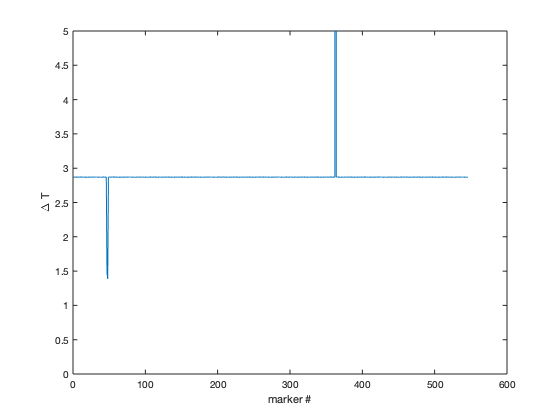

d = diff(sixfours.timestamp);
plot(d)
ylim([0 5])
xlabel('marker #')
ylabel('\Delta T')

height(mrk_table(mrk_table.marker == 2, :))

ans = 36